# **Lab 1:  Random variables and estimation theory**

**Statistical Signal Processing (5CTA0) - Lab Assignment**

Lecturers: Simona Turco, Ivana Nikoloska

Assistants: Yizhou Huang, Luan Fiorio, Agata Barbagini, Xueting Li

**Students (Name + IDs): Roy van Doorn (1484982)**

**Group #: 12**

## General info and guidelines

To complete and submit the Labs:

`•`All students must register on Canvas.

`•`Each lab will be carried out in groups of 3 students, which must register on Canvas.

`•`All information and data will be available on Canvas.

`•`Each group must carry out all assignments of the Lab and hand in a report for each Lab.

`•`**The report is obtained by exporting this matlab live script as pdf. This is the only file that you need to provide. ****If the pdf is missing, a penalization of 1.0 points is given.**

`•`**Sometimes, running the code within livescript might be slow. You may consider to first implment and test your code in a seperate .m file, and copy the code to livescript in the end. **

`•`The report must be submitted through Ans Delft.

`•`In case of problems in submission, please contact the lab assistants. Lab 1: Yizhou Huang: *y.huang2@tue.nl*; Xueting Li: *x.li1@tue.nl**.  *Lab2: Luan Fiorio:* l.v.fiorio@tue.nl*; Agata Barbagini: *a.m.barbagini@tue.nl*. 

`•`The report must be accompanied by the peer-review form, which is used to provide an indication of the contribution of each student in the group. The link to the peer review form is available at [https://forms.office.com/e/D2JnGRWURM](https://forms.office.com/e/D2JnGRWURM)

`•`If plagiarism is detected, the Lab will be judged with 0 points.

**Below, some useful tips for working with MATLAB and for producing a neat Lab report:**

`•`Make use of comments to divide the code in sections and facilitate its understanding.

`•`Use the command `doc or` `help` to learn how to use a specific MATLAB functions (e.g.`doc stem`).

`•`Make sure that all your graphs are easily readable, even when printed in black and white. Use for this purpose the options of the plot/stem function to properly increase the dimension and/or change the marker symbols, for example:

`•`Make sure that all your graphs have their axes properly labeled and a legend when several signals are plotted on the same graph. Also, make sure the all the text is readable. Below some useful commandsfor these purposes:

•To ensure reproducibility, you must use** '**[`rng("default")`](https://nl.mathworks.com/help/matlab/ref/rng.html#d126e1424198)**' **to fix the random seed. 

## Credits and deadlines

Each Lab counts for 15% of the final grade, for a total of 30%. The remaining 70% is determined by the final written exam. 

***Please submit this lab on Canvas by 06/10/2024 at 23:59.***

clear all; close all; clc;

### Part 1: Introduction to random signals

Diabetes Mellitus (DM) type II is a chronic metabolic disease. Patients with DM type II have developed insulin resistance, resulting in high blood glucose levels. DM type II is associated with many health complications, such as cadiovascular disease, kidney disease and vision impairment. The Pima Indians Diabetes Database [1], collected by the National Institute of Diabetes and Digestive and Kidney Diseases is a well-known dataset used for diabetes research. It contains attributes such as age, BMI and blood pressure and an outcome variable which labels which patients have DM type II and which patients do not. The data from this database is stored in the file 'diabetes1.csv'. 

#### ***Exercise 1: Dataset exploration, families of random variables***

a) Load the dataset ('diabetes1.csv') and explore the different features (except the variable 'Outcome', which contains class labels 0 and 1) of the dataset:

- Plot histograms to visualize the distributions. Label each subplot with the corresponding feature.  

- Compute the mean and variance. Do not use the builtin MATLAB functions but implement the functions yourself. Create a table (with feature labels) to present your results. 

*Answer*

diabetes1 = readtable('diabetes1.csv')

diabetes1 = 768×9 table
    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age    Outcome
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___    _______

         6           148           72               35              0      33.6             0.627              50        1   
         1            85           66               29              0      26.6             0.351              31        0   
         8           183           64                0              0      23.3             0.672              32        1   
         1            89           66  

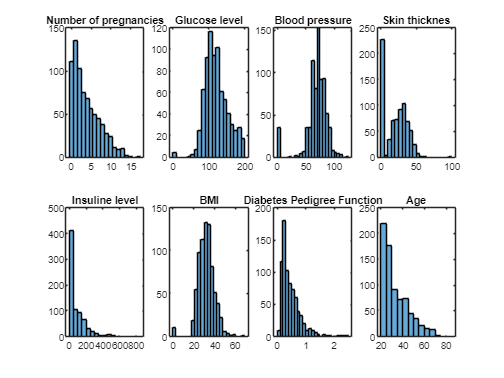

figure(1)
subplot(2,4,1)
histogram(diabetes1.Pregnancies)
title('Number of pregnancies')

subplot(2,4,2)
histogram(diabetes1.Glucose)
title('Glucose level')

subplot(2,4,3)
histogram(diabetes1.BloodPressure)
title('Blood pressure')

subplot(2,4,4)
histogram(diabetes1.SkinThickness)
title('Skin thicknes')

subplot(2,4,5)
histogram(diabetes1.Insulin)
title('Insuline level')

subplot(2,4,6)
histogram(diabetes1.BMI)
title('BMI')

subplot(2,4,7)
histogram(diabetes1.DiabetesPedigreeFunction)
title('Diabetes Pedigree Function')

subplot(2,4,8)
histogram(diabetes1.Age)
title('Age')

mean_table = [mean(diabetes1.Pregnancies), mean(diabetes1.Glucose), mean(diabetes1.BloodPressure), mean(diabetes1.SkinThickness), mean(diabetes1.Insulin), mean(diabetes1.BMI), mean(diabetes1.DiabetesPedigreeFunction), mean(diabetes1.Age)]';
var_table = [var(diabetes1.Pregnancies), var(diabetes1.Glucose), var(diabetes1.BloodPressure), var(diabetes1.SkinThickness), var(diabetes1.Insulin), var(diabetes1.BMI), var(diabetes1.DiabetesPedigreeFunction), var(diabetes1.Age)]';
name_table = categorical({'Pregnancies'; 'Glucose'; 'BloodPressure'; 'SkinThickness'; 'Insulin'; 'BMI'; 'DiabetesPedigreeFunction'; 'Age'});
diabetes1_table = table(name_table, mean_table, var_table, 'VariableNames', {'Name', 'Mean', 'Variance'});
disp(diabetes1_table)

              Name                    Mean               Variance     
    ________________________    _________________    _________________

    Pregnancies                  3.84505208333333     11.3392723931206
    Glucose                          120.89453125     1020.91726175944
    BloodPressure                     69.10546875      374.15944925944
    SkinThickness                20.5364583333333     254.141899956599
    Insulin                      79.7994791666667     13263.8868747288
    BMI                              31.992578125     62.0790464782714
    DiabetesPedigreeFunction    0.471876302083333    0.109635696938409
    Age                          33.2408854166667     138.122963799371



b) Based on your plots in a), determine which RV family would be most appropriate to model the distribution of the feature 'DiabetesPedigreeFunction', among the following RV families; 

- Exponential

- Normal

- Lognormal

- Weibull

In order to do so, fit the data to all four distributions using a MATLAB function and compute the coefficients of determination $\left(R^2 \right)$. Display the fitted distributions on top of histograms of the data and discuss your results. 

Hint: To calculate the $R^2$, make sure that both the fitted distribution and the histogram undergo the same normalization.

*Answer: *

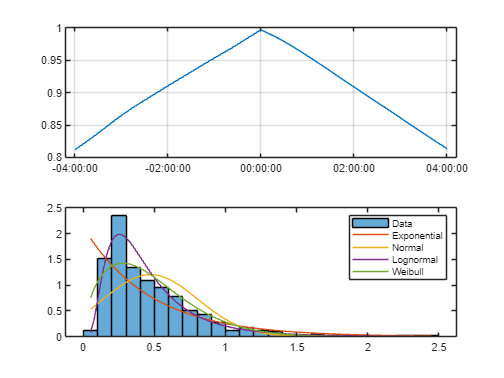

x_values = linspace(0.05, 2.45, 100);
Exponential_fit = pdf(fitdist(diabetes1.DiabetesPedigreeFunction, 'Exponential'), x_values);
Normal_fit = pdf(fitdist(diabetes1.DiabetesPedigreeFunction, 'Normal'), x_values);
Lognormal_fit = pdf(fitdist(diabetes1.DiabetesPedigreeFunction, 'Lognormal'), x_values);
Weibull_fit = pdf(fitdist(diabetes1.DiabetesPedigreeFunction, 'Weibull'), x_values);

figure(2)
histogram(diabetes1.DiabetesPedigreeFunction, 'Normalization','pdf')
hold on
plot(x_values, Exponential_fit)
plot(x_values, Normal_fit)
plot(x_values, Lognormal_fit)
plot(x_values, Weibull_fit)
hold off
legend('Data', 'Exponential', 'Normal', 'Lognormal', 'Weibull')

R_squared_table = [R_squared(Exponential_fit, diabetes1.DiabetesPedigreeFunction), R_squared(Normal_fit, diabetes1.DiabetesPedigreeFunction), R_squared(Lognormal_fit, diabetes1.DiabetesPedigreeFunction), R_squared(Weibull_fit, diabetes1.DiabetesPedigreeFunction)]';
name_table = categorical({'Exponential'; 'Normal'; 'Lognorm'; 'Weibull'});
fit_table = table(name_table, R_squared_table)

fit_table = 4×2 table
    name_table      R_squared_table 
    ___________    _________________

    Exponential    0.461632086600501
    Normal         0.656136087809366
    Lognorm        0.955176023262544
    Weibull        0.840870597264379


The resulting table indicates that the Lognorm RV family results in the best fit. This is also supported by the figure.

c) The central limit theorem states that after averaging multiple realizations of a random variable generated from the same (arbitrary) distribution, the distribution of the averaged random variables converges to a Gaussian distribution. Demonstrate the validity of this theorem through sampling from the fitted distribution of the feature DiabetesPedigree (exercise 1b) for 1, 5, 100 and 10000 realizations. Show your results in one figure with 4 subplots and also report the skewness and kurtosis of each distribution. Discuss your results. 

*Answer:*

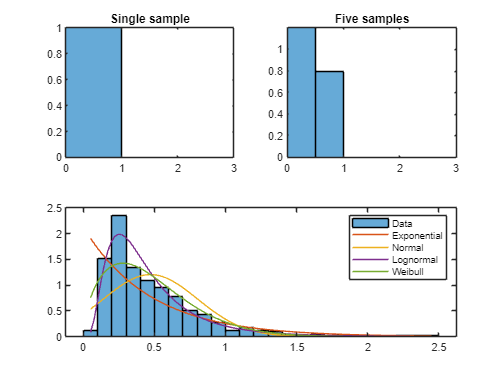

distribution = fitdist(diabetes1.DiabetesPedigreeFunction, 'Lognormal');
single_sample = random(distribution, 1, 1);
five_samples = random(distribution, 5, 1);
hundred_samples = random(distribution, 100, 1);
thousand_samples = random(distribution, 1000, 1);

figure(3)
subplot(2,2,1)
histogram(single_sample, 'Normalization', 'pdf')
xlim([0 3])
title('Single sample')

subplot(2,2,2)
histogram(five_samples, 'Normalization', 'pdf')
xlim([0 3])
title('Five samples')

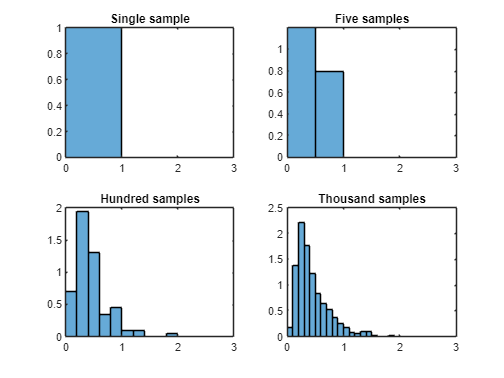


subplot(2,2,3)
histogram(hundred_samples, 'Normalization', 'pdf')
xlim([0 3])
title('Hundred samples')

subplot(2,2,4)
histogram(thousand_samples, 'Normalization', 'pdf')
xlim([0 3])
title('Thousand samples')

skewness_table = [skewness(diabetes1.DiabetesPedigreeFunction); skewness(single_sample); skewness(five_samples); skewness(hundred_samples); skewness(thousand_samples)];
kurtosis_table = [kurtosis(diabetes1.DiabetesPedigreeFunction); kurtosis(single_sample); kurtosis(five_samples); kurtosis(hundred_samples); kurtosis(thousand_samples)];
name_table = categorical({'Original data'; 'Single sample'; 'Five samples'; 'Hundred samples'; 'Thousand samples'});
samples_table = table(name_table, skewness_table, kurtosis_table, 'VariableNames',{'Name', 'Skewness', 'Kurtosis'})

samples_table = 5×3 table
          Name              Skewness             Kurtosis    
    ________________    _________________    ________________

    Original data        1.91615920373863    8.55079204755119
    Single sample                     NaN                 NaN
    Five samples        0.203270862591316    1.31491734369755
    Hundred samples      1.74262755232784    7.12255384227023
    Thousand samples      1.9933507466714    9.64910060493282


#### ***Exercise 2: Probabilities ***

a) Compute the following conditional probabilities using MATLAB operations. Comment your code to explain your approach.  

- P(Age > 50 | Diabetes)

- P(Insulin < 100 | No diabetes) 

*Answer:*

diabetes_indices = diabetes1.Outcome == 1;
age_diabetes_indices = diabetes1.Age > 50 & diabetes1.Outcome == 1;
fprintf('P(Age > 50 | Diabetes) = %.4f\n', sum(age_diabetes_indices)/sum(diabetes_indices))

P(Age > 50 | Diabetes) = 0.1418


diabetes_indices = diabetes1.Outcome == 0;
insulin_diabetes_indices = diabetes1.Insulin < 100 & diabetes1.Outcome == 0;
fprintf('P(Insulin < 100 | Diabetes) = %.4f\n', sum(insulin_diabetes_indices)/sum(diabetes_indices))

P(Insulin < 100 | Diabetes) = 0.7240


b) Are P(Glucose < 100) & P(BloodPressure < 70) independent? Use MATLAB operations to find your answer. Comment your code to explain your approach. 

*Answer:*

% Determine individual probabilities
P_Glucose = mean(diabetes1.Glucose < 100);
P_BloodPressure = mean(diabetes1.BloodPressure < 70);

% Determine joint probability
P_Joint = mean((diabetes1.Glucose < 100) & (diabetes1.BloodPressure < 70));

% Find difference between joint probability and the product of the two indiviual probabilities
fprintf('P(Joint): %.4f, P(Glucose < 100)*P(BloodPressure < 70): %.4f\n', P_Joint, P_Glucose*P_BloodPressure);

P(Joint): 0.1458, P(Glucose < 100)*P(BloodPressure < 70): 0.1062


Sinsce the joint probability and the product of the two individual probabilities are significantly different, it can be said that the two probabilities are independent. 

c) Compute the probability of having diabetes when ‘DiabetesPedigreeFunction' is larger than its mean using Bayes' theorem; 

(1) $\Pr \left\lbrack A|B\right\rbrack =\frac{\Pr \left\lbrack B|A\right\rbrack \Pr \left\lbrack A\right\rbrack }{\Pr \left\lbrack B\right\rbrack }$

Also explain which of the terms in equation (1) is the prior, what it represents, and how the computed probability differs from the prior. 

*Answer:*

P_Diabetes = mean(diabetes1.Outcome);
P_pedigree = mean(diabetes1.DiabetesPedigreeFunction);
P_Pedigree_given_Diabetes = sum(diabetes1.DiabetesPedigreeFunction > P_pedigree & diabetes1.Outcome == 1) / sum(diabetes1.Outcome == 1);
P_Diabetes_given_Pedigree = (P_Pedigree_given_Diabetes * P_Diabetes) / P_pedigree;

fprintf('P(Diabetes|Pedigree > mean) % .4f', P_Diabetes_given_Pedigree);

P(Diabetes|Pedigree > mean)  0.3560

#### ***Exercise 3: Stationarity and ergodicity***

So far, we have investigated feature distributions and probabilities related to features that could help to assess the risk of DM type II. Within the field of diabetes research, another important topic is time series modelling of blood glucose dynamics. Blood glucose dynamics are influenced by many factors, such as insulin levels, carbohydrate intake, exercise and stress. Simglucose [2] is a type-1 diabetes simulator that attemps to model such dynamics. The file 'diabetes2.csv' contains a signal simulated with Simglucose, representing blood glucose and related values of an adolescent over a period of 24 hours. 

a) Load the dataset ('diabetes2.csv') and plot the variables Blood Glucose (BG), Continous Glucose Measurements (CGM), Carbohydrate Intake (CHO) in one figure (using two different scales). 

*Answer:*

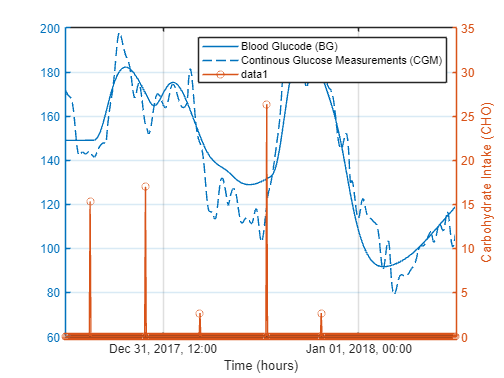

diabetes2 = readtable('diabetes2.csv');

BG = diabetes2.BG;
CGM = diabetes2.CGM;
CHO = diabetes2.CHO;
Time = diabetes2.Time;

clf;
figure(4);
yyaxis left;
plot(Time, BG);

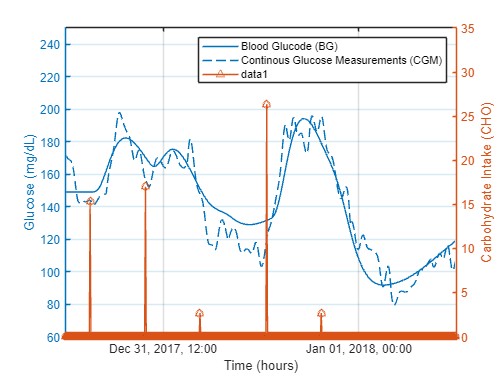

hold on;
plot(Time, CGM);
ylim([60 250]);
ylabel('Glucose (mg/dL)');
legend('Blood Glucode (BG)', 'Continous Glucose Measurements (CGM)')

yyaxis right;
plot(Time, CHO);
ylabel('Carbohydrate Intake (CHO)');
ylim([0 35]);
xlabel('Time (hours)');
grid on;
hold off;

b) Do you think the blood glucose signal is wide-sense stationary? To answer this question, divide the signal into segments, generate plots of relevant statistical parameters and analyze the plots. Does the result correspond with your expectations? Explain your answer. 

*Answer:*

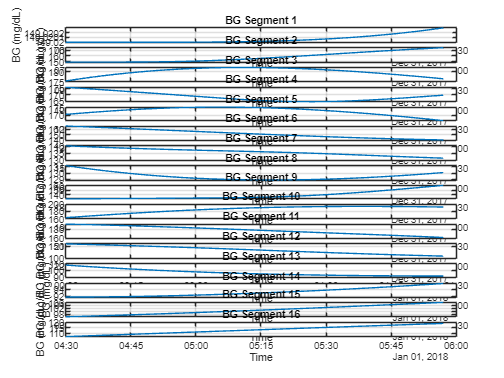

% Extract the BG signal
BG = diabetes2.BG;
Time = diabetes2.Time;

num_segments = 16;
segment_length = floor(length(BG) / num_segments);

means = zeros(num_segments, 1);
variances = zeros(num_segments, 1);

figure;
for i = 1:num_segments
    start_idx = (i-1) * segment_length + 1;
    end_idx = i * segment_length;
    
    BG_segment = BG(start_idx:end_idx);
    Time_segment = Time(start_idx:end_idx);
    
    means(i) = mean(BG_segment);
    variances(i) = var(BG_segment);
    
    subplot(num_segments, 1, i);
    plot(Time_segment, BG_segment);
    title(['BG Segment ', num2str(i)]);
    xlabel('Time');
    ylabel('BG (mg/dL)');
    grid on;
end

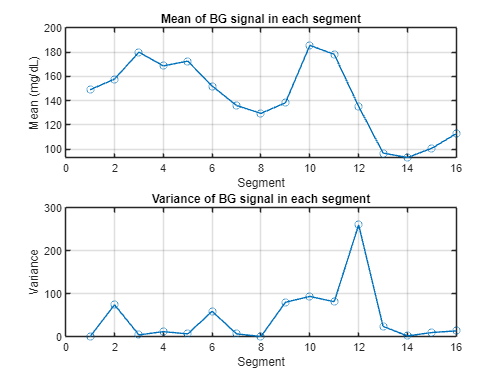

figure;
subplot(2, 1, 1);
plot(1:num_segments, means, '-o');
title('Mean of BG signal in each segment');
xlabel('Segment');
ylabel('Mean (mg/dL)');
grid on;

subplot(2, 1, 2);
plot(1:num_segments, variances, '-o');
title('Variance of BG signal in each segment');
xlabel('Segment');
ylabel('Variance');
grid on;

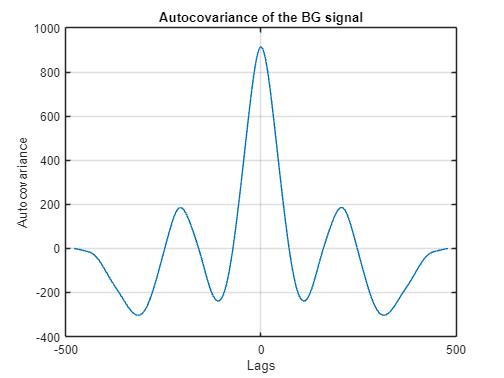


% No mean of signal and variance show significant change --> not wide sense
% stationarity. Can also be seen in autocovariance function (Answer to be refined)

[autocov_BG, lags] = xcov(BG, 'biased'); 

figure;
plot(lags, autocov_BG);
title('Autocovariance of the BG signal');
xlabel('Lags');
ylabel('Autocovariance');
grid on;

c) Compute the cross-correlation between the following signals;

- Blood Glucose and CGM

- Blood Glucose and Carbohydrate Intake

Show your results for lags within a time frame of 4 hours. Do the results correspond with your expectations? Explain your answer. 

*Answer:*

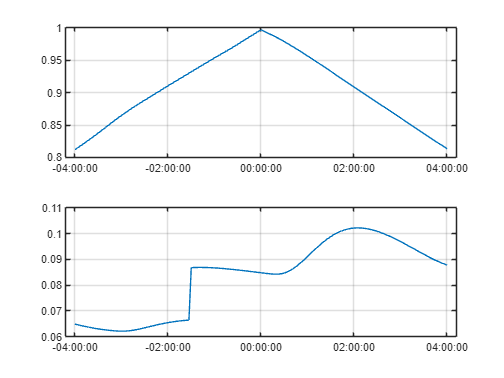

Timestep = mean(diff(Time));
lag_hours = 4;
lag_samples = round(lag_hours / hours(Timestep));

[xcorr_BG_CGM, lags] = xcorr(BG, CGM, lag_samples, 'normalized');
[xcorr_BG_CHO, lags] = xcorr(BG, CHO, lag_samples, 'normalized');
lag_in_hours = lags*Timestep;

figure(5)
subplot(2,1,1);
plot(lag_in_hours, xcorr_BG_CGM);
grid on;

subplot(2,1,2);
plot(lag_in_hours, xcorr_BG_CHO);
grid on;

% Yes supports expectation due to BG and BGM depending on time and
% fluctuating due to this. (Answer to be refined)

d) Estimate the delay (in minutes) between carbohydrate intake and blood glucose increase based on this signal.

*Answer:*

[~, max_corr] = max(xcorr_BG_CHO);
lag_max_corr = lags(max_corr);
delay = lag_max_corr * Timestep;
fprintf('Estimated delay between carb intake and blood glucose increase: %d minutes', minutes(delay));

Estimated delay between carb intake and blood glucose increase: 126 minutes

### Part 2: Estimation theory

A known technique used to estimate the position of a device is based upon analyzing the received signal strength (RSS) from multiple known transmitters. The following article contains useful information about RSS-based localization in the context of estimation theory [3]; 

*Tarrío, P., Bernardos, A. M., & Casar, J. R. (2011). Weighted least squares techniques for improved received signal strength based localization. *

The RSS value decreases with increasing distance from the transmitter, allowing the estimation of distances based on signal strength measurements. The relationship between the received signal power $P_{RX}$ and the distance $d$ from the transmitter can be modeled using the following equation:

(2) $\[ P_{RX}(dBm) = A - 10\eta \log_{10} \left(\frac{d}{d_0}\right) + N \]$

In (2), $A$ represents the received power at a reference distance $d_0$, $\eta$ is the path loss exponent, $d
$ is the distance between the transmitter and receiver, $d_0
$ is the reference distance and $N

$ is a Gaussian random variable representing noise. For this exercise, assume the following values: 

$\eta =3$, $A = -30 dBm$ , $d_0 = 1  m
$

The file 'P_RX.csv' contains the x-, y- and z-coordinates of 50 different transmitters and corresponding received signal power measurements. Based on these received signal power measurements, we will use several techniques to estimate the receiver's location in this part of the assignment. 

#### ***Exercise 4: Maximum Likelihood Estimation***

a) Suppose that we only want to include signals with a signal power above a certain threshold in our analysis. Model the distribution of received signals with a signal power above this threshold for the different transmitters as a Bernoulli distribution. A Bernoulli distribution takes two values; 1 with probability p when the received signal of a transmitter has a signal power that is above the threshold and 0 with probability 1-p when the signal power is below the threshold. Based on this distribution, analytically derive the likelihood function and the MLE. 

*Answer: *

b) For a signal power threshold of -90 dBm, compute the MLE using MATLAB code.

*Answer:*

c) How would you choose the signal power threshold in real life?

*Answer: *

***Exercise 5: Visualization and WGN ***

The received signal power values in 'P_RX.csv' do not contain a noise component yet. In this exercise, we will add white Gaussian noise (WGN) to the measurement values and visualize the effects. 

a) Write MATLAB code that performs the following steps; 

- Discard all measurements below a threshold of -90 dBm. 

- Add a noise component with $N \sim \mathcal{N}(0, \sigma^2)$ to all measurements (with fixed random seed) with $\sigma =1$

- Compute the estimated distance $\hat{d}_i
$ between the receiver and all transmitters, using equation (2)

*Answer:*

b) For the distances of transmitters 1, 9 and 45, visualize the region that is most likely to contain the receiver's location. For each transmitter, plot a sphere with as radius the estimated distance $\hat{d}_i
$. Also annotate the true receiver's location, [5,18,2], in your plot. 

*Answer:*

c) Repeat a) and b) for $\sigma = 0$ and $\sigma = 5
$

What happens to the region of intersection between the 3 different spheres when you change the value of $\sigma$? Why?

*Answer:*

***Exercise 6: (Weighted) Least Squares Estimation***

We will now use a hyperbolic positioning algorithm [3], which converts this problem into a linear problem, to estimate the location of the receiver. To simplify the problem, we will only consider x- and y-coordinates in this exercise. 

For each pair of transmitters, an estimated distance difference can be computed. A constant estimated distance difference defines a hyperbola on which the location of the receiver should lie. The intersection of two or more hyperbolas can be used to determine the users location. 

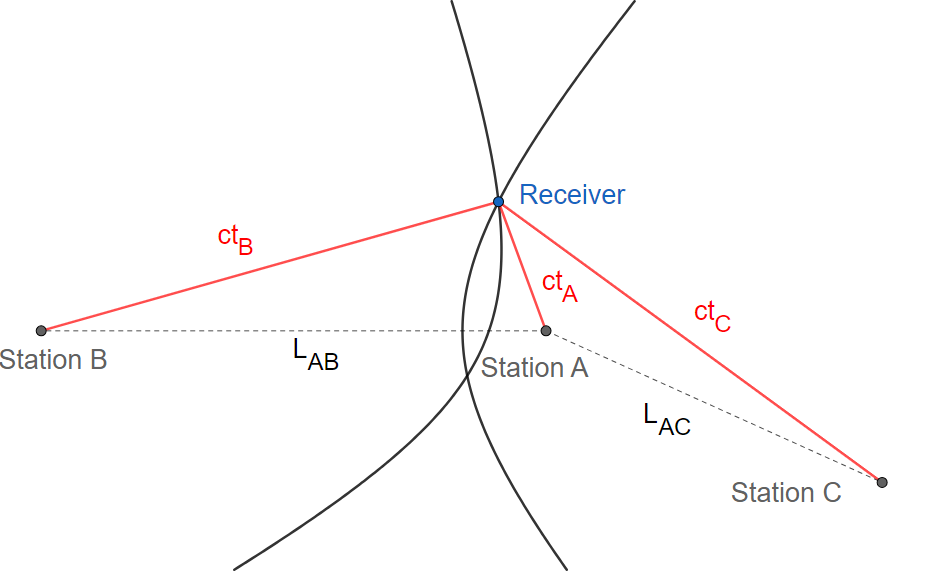

(Image source: [https://en.wikipedia.org/wiki/Hyperbolic_navigation](https://en.wikipedia.org/wiki/Hyperbolic_navigation))

The squared distance between the receiver's location and transmitter node $i$ can be expressed as follows; 

(3) $d_i^2 = (x_i - x)^2 + (y_i - y)^2$ 

If we take the location of the transmitter node with $i=1$at the origin of our coordinate system (so $x_1= 0, y_1=0$), this results in the following equation for $i>1$:

(4) $\(d_i^2 - d_1^2 = x_i^2 - 2xx_i + y_i^2 - 2yy_i\)$

This equation can be expressed in the form $H\bar{x} =\tilde{b}$, with $\bar{x} =\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack$

a) Derive the matrix $H,\;$the vector $\tilde{b}$ and the least-squares estimator. 

*Answer:*

b) Compute the x- and y-coordinates of the receiver node location using your derivations from 6a), using $\sigma =1$ for the measurement noise component.

*Answer: *

In least-squares estimation, equal weight is given to the different distance estimations. However, the accuracy of the RSS measurement and therefore the accuracy of the distance estimation depends on the distance itself. We will therefore now implement a weighted least-squares estimator; 

(5) $\[
\hat{x} = \left( H^T S^{-1} H \right)^{-1} H^T S^{-1} \tilde{b}
\]
$

with matrix S: 


$$S=\left\lbrack \begin{array}{cccc}
\textrm{Var}\left(\tilde{d_1^2 } \right)+\textrm{Var}\left(\tilde{d_2^2 } \right) & \textrm{Var}\left(\tilde{d_1^2 } \right) & \cdots  & \textrm{Var}\left(\tilde{d_1^2 } \right)\\
\textrm{Var}\left(\tilde{d_1^2 } \right) & \textrm{Var}\left(\tilde{d_1^2 } \right)+\textrm{Var}\left(\tilde{d_3^2 } \right) & \cdots  & \textrm{Var}\left(\tilde{d_1^2 } \right)\\
\vdots  & \vdots  & \ddots  & \vdots \\
\textrm{Var}\left(\tilde{d_1^2 } \right) & \textrm{Var}\left(\tilde{d_1^2 } \right) & \cdots  & \textrm{Var}\left(\tilde{d_1^2 } \right)+\textrm{Var}\left(\tilde{d_N^2 } \right)
\end{array}\right\rbrack$$


and

 
$$\textrm{Var}\left(\tilde{d_i^2 } \right)=d_i^4$$


c) Which RSS measurements will get the largest weights? 

*Answer:*

d) Compute the x- and y-coordinates of the receiver node location using the weighted-least squares estimator. 

*Answer:*

e) Compare your results from question 6b) and question 6d). In order to do so, choose a suitable error metric and compute the errors for distances computed with a measurement noise component with $\sigma =1\ldotp \;$Average multiple runs (however many you deem appropriate) and discuss your results. 

*Answer:*

Function definitions

function mean_variable = mean(data)
    len = length(data);
    sum = 0;
    for i=1:len        
        sum = sum + data(i);
    end
    mean_variable = sum/len;
end

function variance_variable = var(data)
    mean_data = mean(data);
    squared_diff = 0;
    for i=1:length(data)
        squared_diff = squared_diff + (data(i)-mean_data)^2;
    end
    variance_variable = squared_diff/length(data);
end

function R_squared_var = R_squared(fit, data)
    [counts, edges] = histcounts(data, 'Normalization', 'pdf');
    bin_centers = (edges(1:end-1) + edges(2:end)) / 2;
    x_values = linspace(0.05, 2.45, 100);
    interp_fit = interp1(x_values, fit, bin_centers);
    RSS = sum((counts - interp_fit).^2);
    TSS = sum((counts - mean(counts)).^2);
    R_squared_var = 1 - (RSS / TSS);
end

*References:*

[1] Kaggle. *Pima Indians Diabetes Database*. Retrieved from [https://www.kaggle.com/datasets/uciml/pima-indians-diabetes-database/data?select=diabetes.csv](https://www.kaggle.com/datasets/uciml/pima-indians-diabetes-database/data?select=diabetes.csv)

[2] Xie, J. (2018). *Simglucose v0.2.1* [Software]. Available from [https://github.com/jxx123/simglucose](https://github.com/jxx123/simglucose)

[3] Tarrío, P., Bernardos, A. M., & Casar, J. R. (2011). Weighted least squares techniques for improved received signal strength based localization. *Sensors (Basel)*, 11(9), 8569-8592. https://doi.org/10.3390/s110908569